# Create a Geometric Transformation for Rotation

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

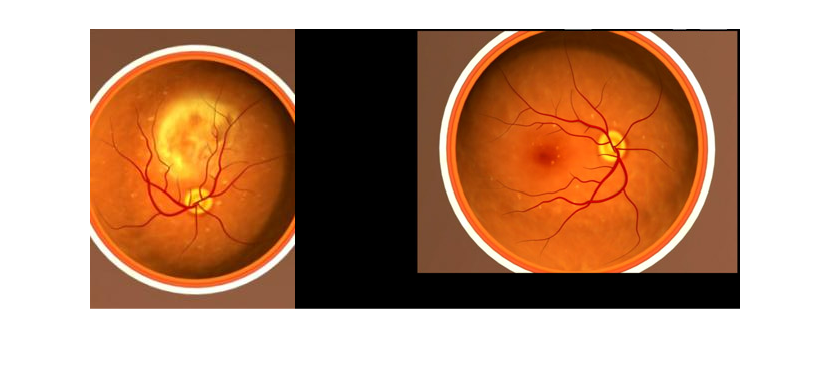

early = imread("./images/earlyAMD.jpg");
advanced = imread("./images/advancedAMD.jpg");
advanced = imrotate(advanced, -90);
imshowpair(advanced, early, "montage")

## Task 1

The eye scan of advanced AMD has been rotated 90° clockwise. You can use `imrotate` to rotate images.

`movTransf` `=` `imrotate``(``moving``,``angle``)``;`

The second input, `angle`, is measured in degrees counterclockwise.

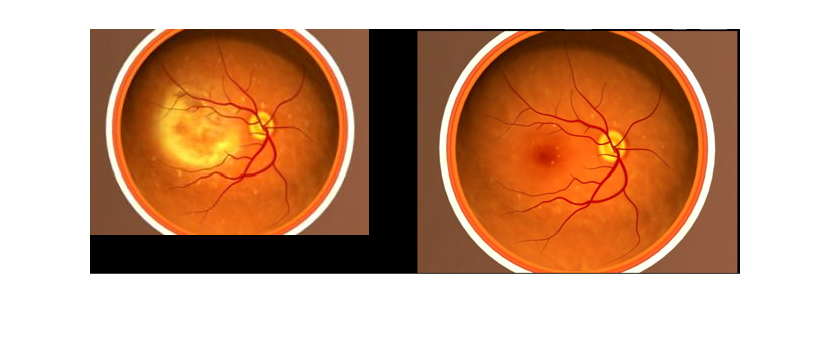

advTransform = imrotate(advanced, 90);
imshowpair(advTransform, early, "montage")

## Task 2

The advanced AMD is slightly zoomed out compared to the early AMD image. You can use `imresize` to change the size of an image.

`movTransf` `=` `imresize``(``moving``,``scale``)``;`

The second input is the scaling factor, which is a positive number. A factor larger than 1 causes the image to increase in size, and a factor smaller than 1 causes it to decrease.

For example, to reduce an image's size by 25%, use a scaling factor of 0.75.

`movTransf` `=` `imresize``(``moving``,``0.75``)``;`

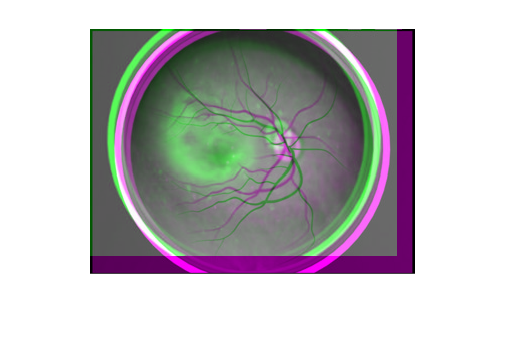

advTransform = imresize(advTransform, 1.1);
imshowpair(advTransform, early)

## Task 3

You can see in the overlay that the advanced AMD scan still needs to be translated. You can use `imtranslate` to translate an image.

`movTransf` `=` `imtranslate``(``moving``,``translation``)``;`

The second input is a two element vector specifying the translations in the *x *and *y* directions.

For example, to shift an image six pixels in the x-direction and seven pixels in the y-direction, use `[``6` `7``]`.

`movTransf` `=` `imtranslate``(``moving``,``[``6` `7``])``;`

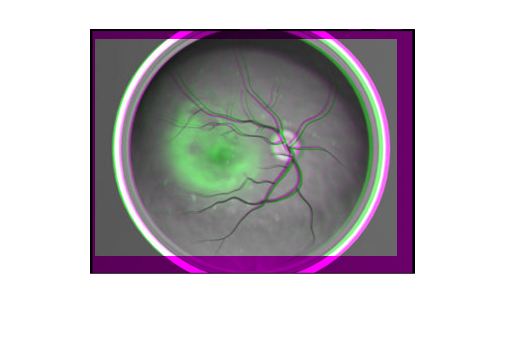

advTransform = imtranslate(advTransform, [5 10]);
imshowpair(advTransform, early)